# Design Task1

clc
clear

## Task1 v_dot_x

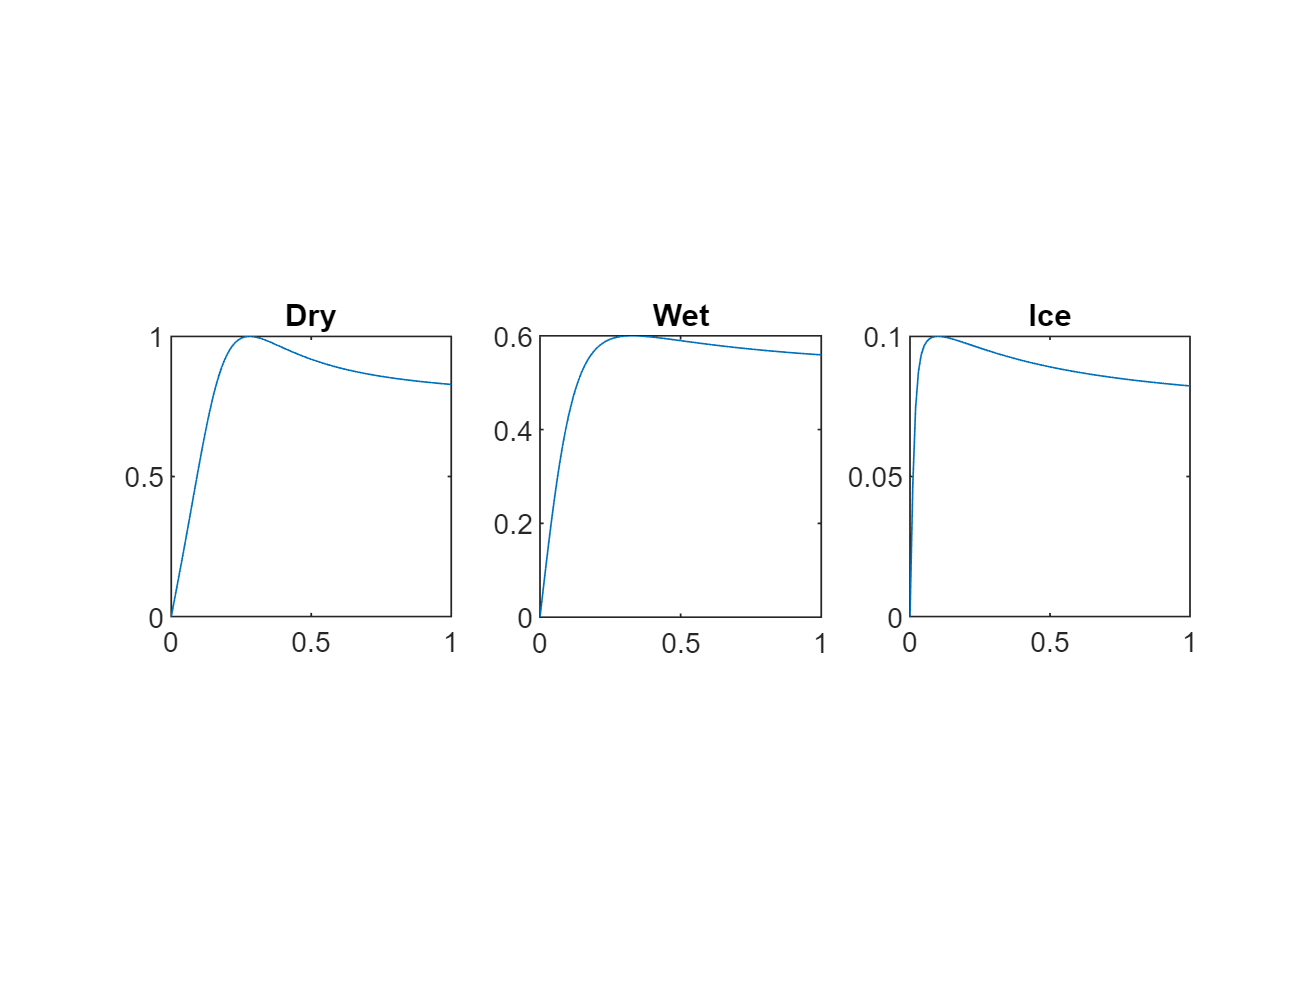

s_x = 0:0.01:1;
[mu_1, surface_type_1] = Sub_magic_tireformula(s_x,1);
[mu_2, surface_type_2] = Sub_magic_tireformula(s_x,2);
[mu_3, surface_type_3] = Sub_magic_tireformula(s_x,3);

figure
subplot(1,3,1)
plot(s_x, mu_1)
title(surface_type_1)
axis square

subplot(1,3,2)
plot(s_x, mu_2)
title(surface_type_2)
axis square
subplot(1,3,3)
plot(s_x, mu_3)
title(surface_type_3)
axis square

## Task1 b

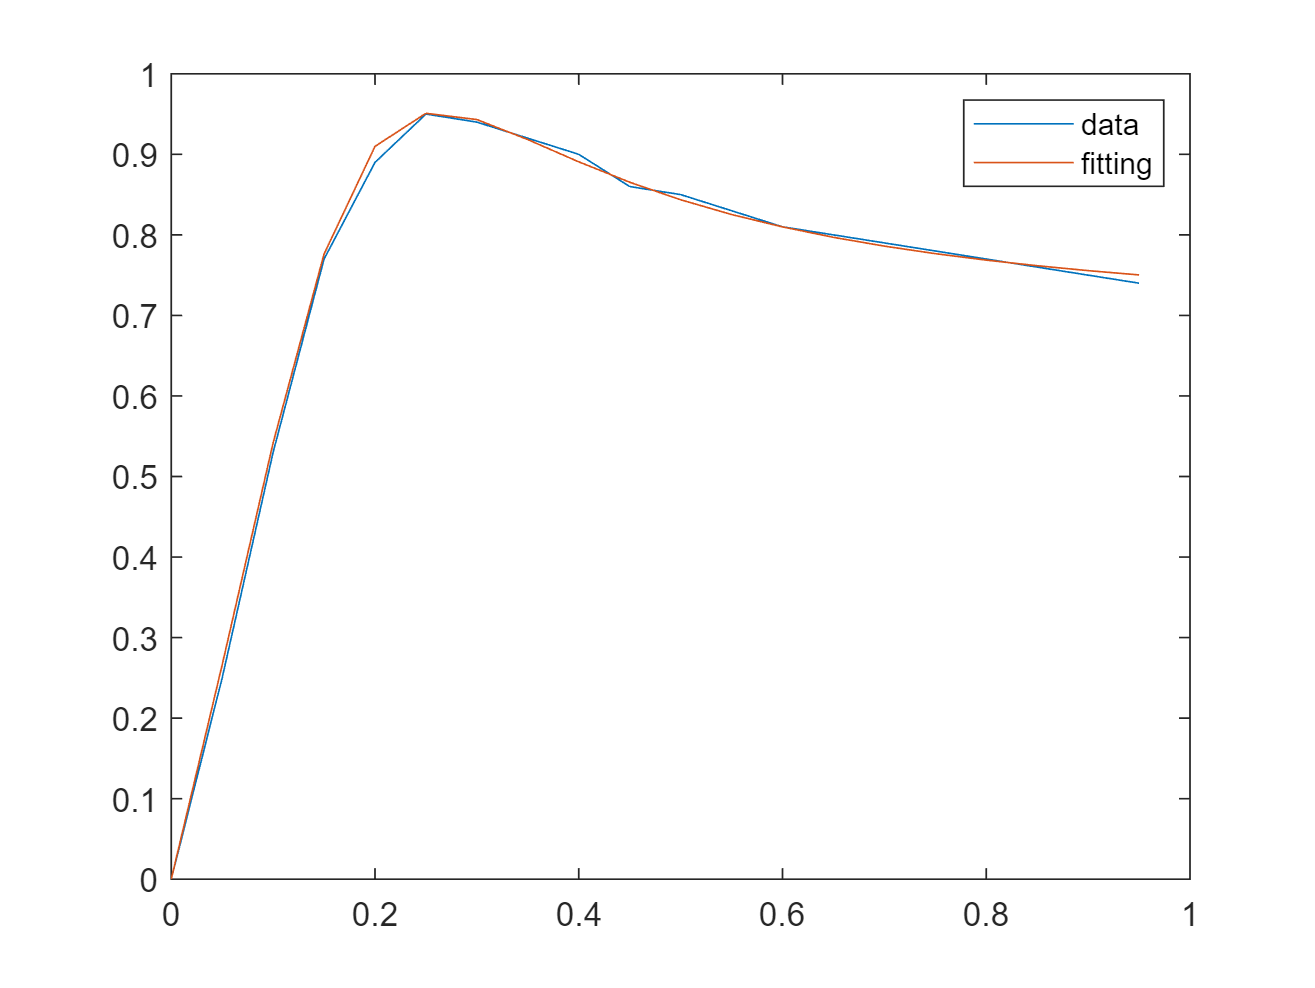

s_x = 0:0.05:0.95;
lf_normd = [0.0 0.25 0.53 0.77 0.89 0.95 0.94 0.92 0.90 0.86 0.85 0.83 0.81 0.80 0.79 0.78 0.77 0.76 0.75 0.74];
mu = magic_tireformula(s_x, 1.5, 0.952, -4.00);
figure 
plot(s_x, lf_normd)
hold on
plot(s_x, mu);
legend("data","fitting")

## Task2

syms F_fx F_rx F_fz F_rz omega_dot_f omega_dot_r v_dot_x 
syms M g L L_f L_r F_air h theta J T_f T_r mu_f mu_r RRC R f_r

% Vertical
equ1 = 0 == F_fz + F_rz - M*g*cos(theta);
% Longitudinal
equ2 = 0 == F_fx + F_rx - F_air - M*v_dot_x - M*g*sin(theta);
% rotation round contact with ground
equ3 = 0 == -M*g*cos(theta)*L_f + F_rz*(L_r+L_f) - (M*g*sin(theta)+M*v_dot_x+F_air)*h;
equ4 = 0 == M*g*cos(theta)*L_r - F_fz*(L_r+L_f) - (M*g*sin(theta)+M*v_dot_x+F_air)*h;
% Equilibrium, rotational
equ5 = 0 == T_f - F_fz*f_r*R - F_fx*R - J*omega_dot_f;
equ6 = 0 == T_r - F_rz*f_r*R - F_rx*R - J*omega_dot_r;
% Constitutive equation
equ7 = F_fx == mu_f * F_fz;
equ8 = F_rx == mu_r * F_rz;

equ9 = 0 == F_rz*L_r - F_fz*L_f - (M*v_dot_x + F_air)*h;

equ = [equ1,equ2, equ3, equ4, equ5,equ6,equ7,equ8];
% equ = [equ1,equ2,equ5,equ6,equ7,equ8,equ9];
sol = solve(equ, [F_fx F_rx F_fz F_rz omega_dot_f omega_dot_r v_dot_x])

sol = struct with fields:
           F_fx: (mu_f*(L_r*M*g*cos(theta) - M*g*h*mu_r*cos(theta)))/(L_f + L_r + h*mu_f - h*mu_r)
           F_rx: (mu_r*(L_f*M*g*cos(theta) + M*g*h*mu_f*cos(theta)))/(L_f + L_r + h*mu_f - h*mu_r)
           F_fz: (L_r*M*g*cos(theta) - M*g*h*mu_r*cos(theta))/(L_f + L_r + h*mu_f - h*mu_r)
           F_rz: (L_f*M*g*cos(theta) + M*g*h*mu_f*cos(theta))/(L_f + L_r + h*mu_f - h*mu_r)
    omega_dot_f: (L_f*T_f + L_r*T_f + T_f*h*mu_f - T_f*h*mu_r - L_r*M*R*f_r*g*cos(theta) - L_r*M*R*g*mu_f*cos(theta) + M*R*f_r*g*h*mu_r*cos(theta) + M*R*g*h*mu_f*mu_r*cos(theta))/(J*(L_f + L_r + h*mu_f - h*mu_r))
    omega_dot_r: -(T_r*h*mu_r - L_r*T_r - T_r*h*mu_f - L_f*T_r + L_f*M*R*f_r*g*cos(theta) + L_f*M*R*g*mu_r*cos(theta) + M*R*f_r*g*h*mu_f*cos(theta) + M*R*g*h*mu_f*mu_r*cos(theta))/(J*(L_f + L_r + h*mu_f - h*mu_r))
        v_dot_x: -(F_air*L_f + F_air*L_r + F_air*h*mu_f - F_air*h*mu_r + L_f*M*g*sin(theta) + L_r*M*g*sin(theta) - L_f*M*g*mu_r*cos(theta) - L_r*M*g*mu_f*cos(theta) 

simplify(sol.F_fz)

$$ans = \frac{M\,g\,\cos\left(\theta \right)\,\left(L_{r}-h\,\mu_{r}\right)}{L_{f}+L_{r}+h\,\mu_{f}-h\,\mu_{r}}$$

simplify(sol.F_rz)

$$ans = \frac{M\,g\,\cos\left(\theta \right)\,\left(L_{f}+h\,\mu_{f}\right)}{L_{f}+L_{r}+h\,\mu_{f}-h\,\mu_{r}}$$

simplify(sol.omega_dot_f)

$$ans = \frac{L_{f}\,T_{f}+L_{r}\,T_{f}+T_{f}\,h\,\mu_{f}-T_{f}\,h\,\mu_{r}-L_{r}\,M\,R\,f_{r}\,g\,\cos\left(\theta \right)-L_{r}\,M\,R\,g\,\mu_{f}\,\cos\left(\theta \right)+M\,R\,f_{r}\,g\,h\,\mu_{r}\,\cos\left(\theta \right)+M\,R\,g\,h\,\mu_{f}\,\mu_{r}\,\cos\left(\theta \right)}{J\,\left(L_{f}+L_{r}+h\,\mu_{f}-h\,\mu_{r}\right)}$$

simplify(sol.omega_dot_r)

$$ans = -\frac{T_{r}\,h\,\mu_{r}-L_{r}\,T_{r}-T_{r}\,h\,\mu_{f}-L_{f}\,T_{r}+L_{f}\,M\,R\,f_{r}\,g\,\cos\left(\theta \right)+L_{f}\,M\,R\,g\,\mu_{r}\,\cos\left(\theta \right)+M\,R\,f_{r}\,g\,h\,\mu_{f}\,\cos\left(\theta \right)+M\,R\,g\,h\,\mu_{f}\,\mu_{r}\,\cos\left(\theta \right)}{J\,\left(L_{f}+L_{r}+h\,\mu_{f}-h\,\mu_{r}\right)}$$

simplify(sol.v_dot_x)

$$ans = -\frac{F_{\mathrm{air}}\,L_{f}+F_{\mathrm{air}}\,L_{r}+F_{\mathrm{air}}\,h\,\mu_{f}-F_{\mathrm{air}}\,h\,\mu_{r}+L_{f}\,M\,g\,\sin\left(\theta \right)+L_{r}\,M\,g\,\sin\left(\theta \right)-L_{f}\,M\,g\,\mu_{r}\,\cos\left(\theta \right)-L_{r}\,M\,g\,\mu_{f}\,\cos\left(\theta \right)+M\,g\,h\,\mu_{f}\,\sin\left(\theta \right)-M\,g\,h\,\mu_{r}\,\sin\left(\theta \right)}{M\,\left(L_{f}+L_{r}+h\,\mu_{f}-h\,\mu_{r}\right)}$$

%%
% Ffz=
(L_r*M*g*cos(theta) - M*g*h*mu_r*cos(theta))/(L_f + L_r + h*mu_f - h*mu_r);
% Frz =
(L_f*M*g*cos(theta) + M*g*h*mu_f*cos(theta))/(L_f + L_r + h*mu_f - h*mu_r);
% w_dot_f =
(L_f*T_f + L_r*T_f + T_f*h*mu_f - T_f*h*mu_r - L_r*M*R*f_r*g*cos(theta) - L_r*M*R*g*mu_f*cos(theta) + M*R*f_r*g*h*mu_r*cos(theta) + M*R*g*h*mu_f*mu_r*cos(theta))/(J*(L_f + L_r + h*mu_f - h*mu_r));
% w_dot_r =
-(T_r*h*mu_r - L_r*T_r - T_r*h*mu_f - L_f*T_r + L_f*M*R*f_r*g*cos(theta) + L_f*M*R*g*mu_r*cos(theta) + M*R*f_r*g*h*mu_f*cos(theta) + M*R*g*h*mu_f*mu_r*cos(theta))/(J*(L_f + L_r + h*mu_f - h*mu_r));
% v_dot_x =
-(F_air*L_f + F_air*L_r + F_air*h*mu_f - F_air*h*mu_r + L_f*M*g*sin(theta) + L_r*M*g*sin(theta) - L_f*M*g*mu_r*cos(theta) - L_r*M*g*mu_f*cos(theta) + M*g*h*mu_f*sin(theta) - M*g*h*mu_r*sin(theta))/(M*(L_f + L_r + h*mu_f - h*mu_r));





eq1 = M*v_dot_x == F_fx + F_rx - F_air - M*g*sin(theta);
%Chassi horizontal
eq2 = M*g*cos(theta) == F_fz + F_rz;
%Moment front wheel
eq3 = 0 == -M*g*cos(theta)*L_f+F_rz*(L_r+L_f)- F_air*(h-R);
%Moment rear wheel
eq4 = 0 == M*g*cos(theta)*L_r-F_fz*(L_r+L_f) - F_air*(h-R);

%Tyre equations
%   Moment front tyre
eq5 = J*omega_dot_f == T_f-F_fx*R-F_fz*f_r*R;
%Force horizontal front tyre
eq6 = F_fx == F_fz*mu_f;
%Moment rear tyre
eq7 = J*omega_dot_r == T_r-F_rx*R-F_fz*f_r*R;
%Force horizontal rear tyre
eq8 = F_rx == F_rz*mu_r; %
equ = [equ1,equ2, equ3, equ4, equ5,equ6,equ7,equ8];
vars = [F_fx F_rx F_fz F_rz omega_dot_f omega_dot_r v_dot_x];
% equ = [equ1,equ2,equ5,equ6,equ7,equ8,equ9];
sol = solve(equ, vars)

sol = struct with fields:
           F_fx: (mu_f*(L_r*M*g*cos(theta) + M*R*g*mu_r*cos(theta) - M*g*h*mu_r*cos(theta)))/(L_f + L_r - R*mu_f + R*mu_r + h*mu_f - h*mu_r)
           F_rx: (mu_r*(L_f*M*g*cos(theta) - M*R*g*mu_f*cos(theta) + M*g*h*mu_f*cos(theta)))/(L_f + L_r - R*mu_f + R*mu_r + h*mu_f - h*mu_r)
           F_fz: (L_r*M*g*cos(theta) + M*R*g*mu_r*cos(theta) - M*g*h*mu_r*cos(theta))/(L_f + L_r - R*mu_f + R*mu_r + h*mu_f - h*mu_r)
           F_rz: (L_f*M*g*cos(theta) - M*R*g*mu_f*cos(theta) + M*g*h*mu_f*cos(theta))/(L_f + L_r - R*mu_f + R*mu_r + h*mu_f - h*mu_r)
    omega_dot_f: (L_f*T_f + L_r*T_f - R*T_f*mu_f + R*T_f*mu_r + T_f*h*mu_f - T_f*h*mu_r - M*R^2*f_r*g*mu_r*cos(theta) - M*R^2*g*mu_f*mu_r*cos(theta) - L_r*M*R*f_r*g*cos(theta) - L_r*M*R*g*mu_f*cos(theta) + M*R*f_r*g*h*mu_r*cos(theta) + M*R*g*h*mu_f*m…
    omega_dot_r: (L_f*T_r + L_r*T_r - R*T_r*mu_f + R*T_r*mu_r + T_r*h*mu_f - T_r*h*mu_r + M*R^2*f_r*g*mu_f*cos(theta) + M*R^2*g*mu_f*mu_r*cos(theta) - L_f*M*R*f_r*g*cos(the

simplify(sol.F_fz)

$$ans = \frac{M\,g\,\cos\left(\theta \right)\,\left(L_{r}+R\,\mu_{r}-h\,\mu_{r}\right)}{L_{f}+L_{r}-R\,\mu_{f}+R\,\mu_{r}+h\,\mu_{f}-h\,\mu_{r}}$$

simplify(sol.F_rz)

$$ans = \frac{M\,g\,\cos\left(\theta \right)\,\left(L_{f}-R\,\mu_{f}+h\,\mu_{f}\right)}{L_{f}+L_{r}-R\,\mu_{f}+R\,\mu_{r}+h\,\mu_{f}-h\,\mu_{r}}$$

simplify(sol.omega_dot_f)

$$ans = \frac{L_{f}\,T_{f}+L_{r}\,T_{f}-R\,T_{f}\,\mu_{f}+R\,T_{f}\,\mu_{r}+T_{f}\,h\,\mu_{f}-T_{f}\,h\,\mu_{r}-M\,R^{2}\,f_{r}\,g\,\mu_{r}\,\cos\left(\theta \right)-M\,R^{2}\,g\,\mu_{f}\,\mu_{r}\,\cos\left(\theta \right)-L_{r}\,M\,R\,f_{r}\,g\,\cos\left(\theta \right)-L_{r}\,M\,R\,g\,\mu_{f}\,\cos\left(\theta \right)+M\,R\,f_{r}\,g\,h\,\mu_{r}\,\cos\left(\theta \right)+M\,R\,g\,h\,\mu_{f}\,\mu_{r}\,\cos\left(\theta \right)}{J\,\left(L_{f}+L_{r}-R\,\mu_{f}+R\,\mu_{r}+h\,\mu_{f}-h\,\mu_{r}\right)}$$

simplify(sol.omega_dot_r)

$$ans = \frac{L_{f}\,T_{r}+L_{r}\,T_{r}-R\,T_{r}\,\mu_{f}+R\,T_{r}\,\mu_{r}+T_{r}\,h\,\mu_{f}-T_{r}\,h\,\mu_{r}+M\,R^{2}\,f_{r}\,g\,\mu_{f}\,\cos\left(\theta \right)+M\,R^{2}\,g\,\mu_{f}\,\mu_{r}\,\cos\left(\theta \right)-L_{f}\,M\,R\,f_{r}\,g\,\cos\left(\theta \right)-L_{f}\,M\,R\,g\,\mu_{r}\,\cos\left(\theta \right)-M\,R\,f_{r}\,g\,h\,\mu_{f}\,\cos\left(\theta \right)-M\,R\,g\,h\,\mu_{f}\,\mu_{r}\,\cos\left(\theta \right)}{J\,\left(L_{f}+L_{r}-R\,\mu_{f}+R\,\mu_{r}+h\,\mu_{f}-h\,\mu_{r}\right)}$$

simplify(sol.v_dot_x)

$$ans = -\frac{F_{\mathrm{air}}\,L_{f}+F_{\mathrm{air}}\,L_{r}-F_{\mathrm{air}}\,R\,\mu_{f}+F_{\mathrm{air}}\,R\,\mu_{r}+F_{\mathrm{air}}\,h\,\mu_{f}-F_{\mathrm{air}}\,h\,\mu_{r}+L_{f}\,M\,g\,\sin\left(\theta \right)+L_{r}\,M\,g\,\sin\left(\theta \right)-L_{f}\,M\,g\,\mu_{r}\,\cos\left(\theta \right)-L_{r}\,M\,g\,\mu_{f}\,\cos\left(\theta \right)-M\,R\,g\,\mu_{f}\,\sin\left(\theta \right)+M\,R\,g\,\mu_{r}\,\sin\left(\theta \right)+M\,g\,h\,\mu_{f}\,\sin\left(\theta \right)-M\,g\,h\,\mu_{r}\,\sin\left(\theta \right)}{M\,\left(L_{f}+L_{r}-R\,\mu_{f}+R\,\mu_{r}+h\,\mu_{f}-h\,\mu_{r}\right)}$$

fprintf("string %s", sol.F_fx)

string (mu_f*(L_r*M*g*cos(theta) + M*R*g*mu_r*cos(theta) - M*g*h*mu_r*cos(theta)))/(L_f + L_r - R*mu_f + R*mu_r + h*mu_f - h*mu_r)

function mu = magic_tireformula(slip,C,D,E0)
%----Common parameters-----------------------------------------------------
K  = 3*pi/180;
B  = atan(K)/(C*D);

%----Calculate the available friction--------------------------------------
mu = D*sin(C*atan(B*slip*100-E0*(B*slip*100-atan(B*slip*100))));

end